 % Take the firsimage and convert in rgb2 gray

img = cell(1,6);
for ind = 1:6
    img{ind} = imread(strcat("ur_c_s_03a_01_L_03", num2str((ind+75)),".png"));
    img{ind} = colorToDouble(img{ind});
end


Find the red car

% % Find the window around the red car
% window_red = img{1}(359:430,688:770);
% c = normxcorr2(window_red,img{1});
% [ypeak,xpeak] = find(c==max(c(:)));
% figure, imagesc(c), colormap gray, title("max of cross correlation in image ")
% hold on
% plot(xpeak, ypeak, "*r"),"LineWidth",2, "EdgeColor",[1 0 0];
% % imagefilename="Images/ncc_red_car";
% % print(imagefilename,"-dpng");
% 
% figure, imagesc(window_red), colormap gray, title("window of red car")
% imagefilename="Images/window_red_car";
% print(imagefilename,"-dpng");
% 
% % Pint all the photos of the red car
% for k = 1:6
%     RectDetection(window_red, img{k}, k);
% end

Find the black car

% % Small windows, window 1
% window_black1 = img{1}(395:400, 595:600);
% figure, imagesc(window_black1), colormap gray,title("window small black car");
% % imagefilename="Images/window_black_car_small";
% % print(imagefilename,"-dpng");
% 
% 
% comp_time_window = zeros(3, 6);
% % Pint all the photos of the black car, smoller window
% for k = 1:6
%     c1 = RectDetection(window_black1, img{k}, k);
%     comp_time_window(1, k) = c1;
% 
% end


% % Medium window, window 2
% window_black2 = img{1}(385:405, 575:610);
% figure, imagesc(window_black2), colormap gray,title("window medium black car");
% imagefilename="Images/window_black_car_medium";
% print(imagefilename,"-dpng");
% 
% 
% % Pint all the photos of the black car, normal window
% for k = 1:6
%     c2 = RectDetection(window_black2, img{k}, k);
%     comp_time_window(2, k) = c2;
% 
% end


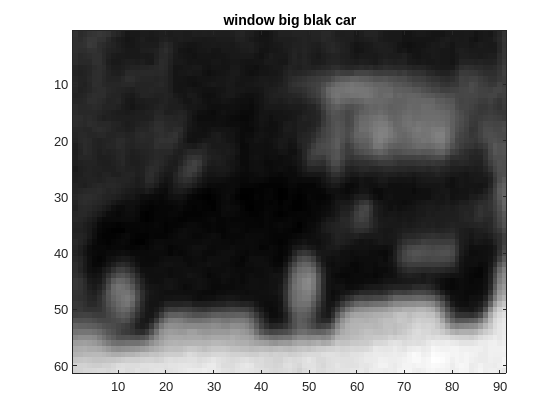

% Big window, window 3
window_black3 = img{1}(360:420, 555:645);
figure, imagesc(window_black3), colormap gray, title("window big blak car");
imagefilename="Images/window_black_car_big";
print(imagefilename,"-dpng");


% Pint all the photos of the black car, bigger window
for k = 1:6
    c3 = RectDetection(window_black3, img{k}, k);
    comp_time_window(3, k) = c3;
end

computational_time = 0.5841

ans = "LineWidth"

ans = 2

ans = "EdgeColor"


sum_compTime = sum(comp_time_window')
mean_compTime = mean (comp_time_window')



Punto 2

% %Harris corner detector
% 
% tmp=imread('i235.png');
% I=double(tmp);
% figure,imagesc(I),colormap gray
% 
% %compute x and y derivative of the image using sobel
% dx=[1 0 -1; 2 0 -2; 1 0 -1];
% dy=[1 2 1; 0  0  0; -1 -2 -1];
% Ix=conv2(I,dx,'same');
% Iy=conv2(I,dy,'same');
% figure,imagesc(Ix),colormap gray,title('Ix')
% figure,imagesc(Iy),colormap gray,title('Iy')
% 
% %compute products of derivatives at every pixel
% % Compute second drivate
% Ix2=Ix.*Ix; 
% Iy2=Iy.*Iy; 
% Ixy=Ix.*Iy;
% 
% %compute the sum of products of  derivatives at each pixel
% g = fspecial('gaussian', 9, 1.2);
% figure,imagesc(g),colormap gray,title('Gaussian')
% Sx2=conv2(Ix2,g,'same'); 
% Sy2=conv2(Iy2,g,'same'); 
% Sxy=conv2(Ixy,g,'same');
% 
% %features detection
% [rr,cc]=size(Sx2);
% edge_reg=zeros(rr,cc); 
% corner_reg=zeros(rr,cc); 
% flat_reg=zeros(rr,cc);
% R_map=zeros(rr,cc);
% k=0.05;
% 
% for ii=1:rr
%     for jj=1:cc
%         %define at each pixel x,y the matrix
%         M=[Sx2(ii,jj),Sxy(ii,jj);Sxy(ii,jj),Sy2(ii,jj)];
%         %compute the response of the detector at each pixel
%         R=det(M) - k*(trace(M).^2);
%         R_map(ii,jj)=R;
%     end 
% end
% threshold = 0.3 * max(R_map, [], "all");
% 
% 
% 
% for ii=1:rr
%     for jj=1:cc
%         %define at each pixel x,y the matrix
%         M=[Sx2(ii,jj),Sxy(ii,jj);Sxy(ii,jj),Sy2(ii,jj)];
%         %compute the response of the detector at each pixel
%         R=det(M) - k*(trace(M).^2);
%         R_map(ii,jj)=R;
%         if R < -threshold
%             edge_reg(ii,jj)=1;
%         end
%         if R > threshold
%             corner_reg(ii,jj)=1;
%         end
%         if abs(R) < threshold
%             flat_reg(ii, jj) = 1;
%         end
%     end
% end
% 
% prop = regionprops(corner_reg > 0, "Centroid");
% hold on
% figure,imagesc(edge_reg.*I),colormap gray,title('edge regions')
% figure,imagesc(corner_reg.*I),colormap gray,title('corner regions')
% figure,imagesc(flat_reg.*I),colormap gray,title('flat regions')
% figure,imagesc(R_map),colormap jet,title('R map')



function [img] = colorToDouble (img)
%Function that transform the image rom color to gray    
    img = rgb2gray(img);
    img = double(img);
end



function computational_time = RectDetection (window, img, k)

tic

%Do the NCC with the image and the window
c = normxcorr2(window,img);
%figure, imagesc(c), colormap gray, title("image cross correlated");

% Find the peak in cross correlation(white point)
[ypeak,xpeak] = find(c==max(c(:)));

yoffSet = ypeak-size(window,1);
xoffSet = xpeak-size(window,2);

yoff = ypeak - (size(window,1)/2);
xoff = xpeak - (size(window,2)/2);




computational_time = toc

figure, imagesc(img), colormap("gray"), title("black car big window");
hold on
plot(xoff, yoff, "*r"),"LineWidth",2, "EdgeColor",[1 0 0];
rectangle('Position',[xoffSet yoffSet size(window,2) size(window,1)],"LineWidth",2, "EdgeColor",[1 0 0] )
imagefilename=sprintf("Images/black_car_big_(%d)", k);
print(imagefilename,"-dpng");


end






